#     FEM2D: Thermal problem with Convection BC using Triangular Elements

**Source: **taken from professor Toni Susin's [Numerical Factory 2019](https://numfactory.upc.edu/web/FiniteElements/Pract/P8-FEM2D/P8.3.FEM2DThermalTriangConvectionSmall/P8.3.FEM2DThermalTriangConvectionSmall.html).

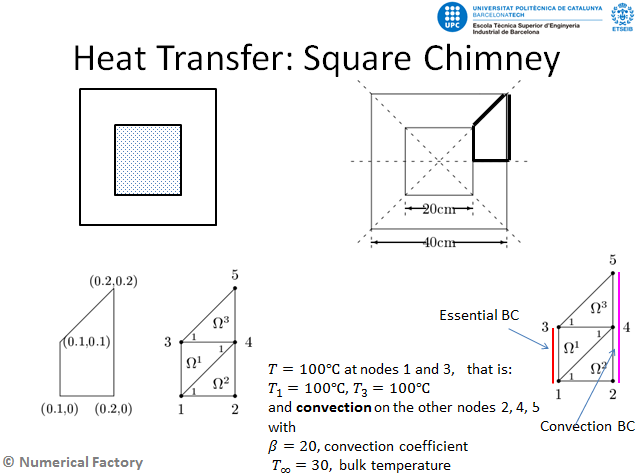

Assume $k_{c} = a_{11} = a_{22} = 1$, $a_{12}=a_{21}= a_{00} = f = 0$, so we consider the thermal equation $-\frac{\partial^{2} u}{\partial x^{2}}-\frac{\partial^{2} u}{\partial y^{2}} = 0$, with the B.C. shown in the figure above.

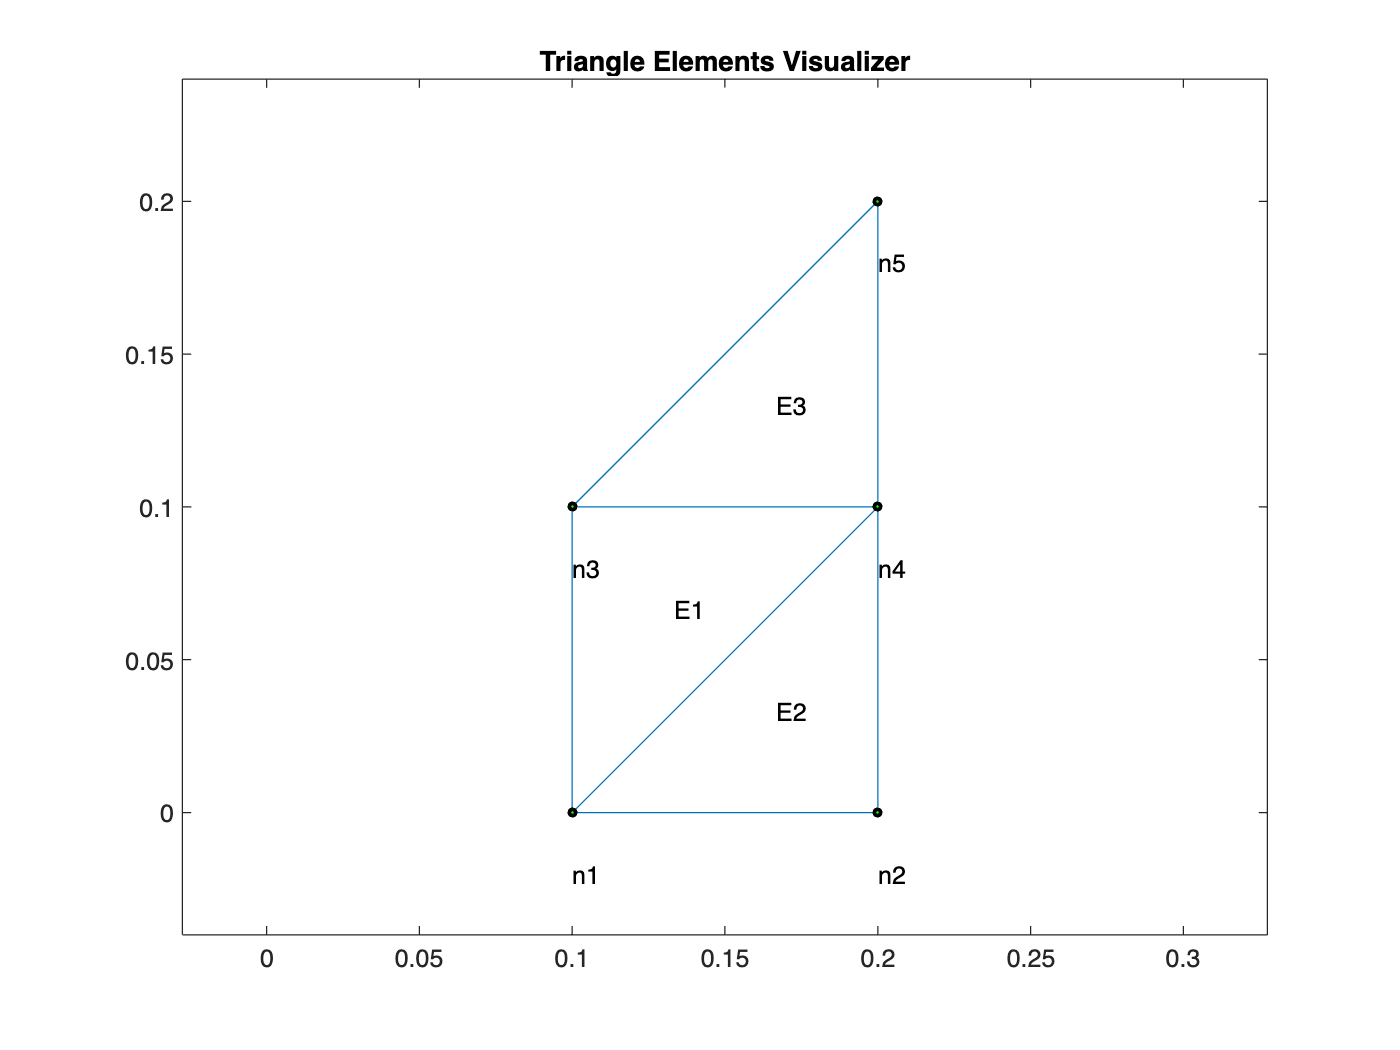

clearvars
close all

a11=1.0;
a12=0.0;
a21=a12;
a22=a11;
a00=0.0;
f=0.0;

T=100.0;
beta=20;
Tinf=30;

nodes=[
    0.1,0.0;
    0.2,0.0;
    0.1,0.1;
    0.2,0.1;
    0.2,0.2
    ];
elem=[
    4,3,1;
    1,2,4;
    3,4,5;
    ];
numNod=size(nodes,1);
numElem=size(elem,1);
numbering=1;
%plotElements(nodes,elem,numbering);
plotElementsOld(nodes, elem, numbering)

### Computation of $K^{e}$ and $F^{e}$

Here we can use formulas for Poisson equation ($a_{11} = a_{22} = c, a_{12} = a_{21} =a_{00} = 0$) on right triangles (see the slides, and recall that then, local node $2$ mus be placed at the right angle). Then, on the one hand it follows at once that


$$K^ {e} = \frac{1}{6}\left(\begin{array}{rrr}
3 & -3 & 0\\
-3 & 6 & -3\\
0 & -3 & 3\end{array}\right),\qquad
F^{e} = \left(\begin{array}{c} 0\\ 0\\ 0\end{array}\right).$$


for $e = 1,2,3$. On the other fand, as $f\equiv 0$ (no heat sources inside the domain), then $F^{e} = 0$  for $e= 1,2,3$

### Assembled matrices


$$\left(\begin{array}{ccccc}
K_{3,3}^{1} + K_{1,1}^{2} & K_{1,2}^{2} & K_{3,2}^{1} & K_{3,1}^{1} + K_{1,3}^{2} & 0\\
K_{2,1}^{2} & K_{2,2}^{2} & 0 & K_{2,3}^{2} & 0\\
K_{2,3}^{1} & 0 & K_{2,2}^{1} + K_{1,1}^{3} & K_{2,1}^{1} + K_{1,2}^{3} & K_{1,3}^{3}\\
K_{1,3}^{1} + K_{3,1}^{2} & K_{3,2}^{2} & K_{1,2}^{1} + K_{2,1}^{3} & K_{1,1}^{1} + K_{3,3}^{2} + K_{2,2}^{3} & K_{2,3}^{3}\\
0 & 0 & K_{3,1}^{3} & k_{3,2}^{3} & K_{3,3}^{3}
\end{array}\right) = 
\frac{1}{6}\left(\begin{array}{rrrrr}
6 & -3 & -3 & 0 & 0\\
-3 & 6 & 0 & -3 & 0\\
-3 & 0 & 9 & -6 & 0\\
0 & -3 & -6 & 12 & -3\\
0 & 0 & 0 & -3 & 3
\end{array}\right),\qquad
\left(\begin{array}{c}
F_{1}\\ F_{2}\\ F_{3}\\ F_{4} \\ F_{5}\end{array}\right) =
\left(\begin{array}{c}   
F_{3}^{1} + F_{1}^{2}\\
F_{2}^{2}\\
F_{2}^{1} + F_{1}^{3}\\
F_{1}^{1} + F_{3}^{2} + F_{2}^{3}\\
F_{3}^{3}
\end{array}\right) =
\left(\begin{array}{c}
0\\ 0\\ 0\\ 0\\ 0
\end{array}\right),\qquad
\left(\begin{array}{c}
Q_{1}\\ Q_{2}\\ Q_{3}\\ Q_{4} \\ Q_{5}\end{array}\right) =
\left(\begin{array}{c}
Q_{3}^{1} + Q_{1}^{2}\\
Q_{2}^{2}\\
Q_{2}^{1} + Q_{1}^{3}\\
Q_{1}^{1} + Q_{3}^{2} + Q_{2}^{3}\\
Q_{3}^{3}
\end{array}\right).$$


### Assembled system


$$\frac{1}{6}\left(\begin{array}{rrrrr}
6 & -3 & -3 & 0 & 0\\
-3 & 6 & 0 & -3 & 0\\
-3 & 0 & 9 & -6 & 0\\
0 & -3 & -6 & 12 & -3\\
0 & 0 & 0 & -3 & 3
\end{array}\right)  
\left(\begin{array}{c} T_{1}\\ T_{2}\\ T_{3}\\ T_{4} \\ T_{5}
\end{array}\right) =
\left(\begin{array}{c}
F_{1}\\ F_{2}\\ F_{3}\\ F_{4} \\ F_{5}\end{array}\right) +
\left(\begin{array}{c} 
Q_{1}\\ Q_{2}\\ Q_{3}\\ Q_{4} \\ Q_{5}\end{array}\right),$$


with $F_{i} = 0$, for $i = 1,2,,3,4,5$, since $f\equiv 0$. 

%Assemble system
K=zeros(numNod);
Q=zeros(numNod,1);
F=zeros(numNod,1);

coeff=[a11,a12,a21,a22,a00,f];

for e=1:numElem
    [Ke,Fe]=linearTriangElement(coeff,nodes,elem,e);
    rows=elem(e,:);
    cols=rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows) = F(rows) + Fe;
    end
end
Kini = K; %save a copy of the stifness matrix for the post porcess


### Boundary Conditions

#### Natural Boundary Conditions


$$\begin{array}{l}
Q_{2}  = Q^ {2}_{2} = Q^{2}_{22} = -\beta\left(\frac{T_{2}}{3} + \frac{T_{4}}{6}\right) h^{2}_{2} + \beta h^{2}_{2}\frac{T_{\infty}}{2} = 
-\frac{2}{3} T_{2} - \frac{1}{3} T_{4} + 30,\\
Q_{4}  = Q^{2}_{3} + Q^{3}_{2} = Q^ {2}_{32} + Q^{3}_{22} =
 -\beta\left(\frac{T_{2}}{6} + \frac{T_{4}}{3}\right) h^{2}_{2} + \beta h^{2}_{2}\frac{T_{\infty}}{2}  - \beta \left(\frac{T_{4}}{3} + \frac{T_{5}}{6}\right) h^{3}_{2} + \beta h^{3}_{2}\frac{T_{\infty}}{2} =
-\frac{1}{3} T_{2} - \frac{4}{3} T_{4} - \frac{1}{3} T_{5} + 60,\\
Q_{5}  = Q^ {3}_{3} = Q^{3}_{32} = -\beta\left(\frac{T_{4}}{6} + \frac{T_{5}}{3}\right) h^{3}_{2} + \beta h^{3}_{2}\frac{T_{\infty}}{2} = 
-\frac{1}{3} T_{4} - \frac{2}{3} T_{5} + 30,
\end{array}$$


($h^{2}_{2} = h^{3}_{2} = 1/10, \beta = 20, T_{\infty} = 30$), or, in matrix notation


$$\left(\begin{array}{c} Q_{2}\\ Q_{4} \\ Q_{5}\end{array}\right) =
-\frac{1}{6}\left(\begin{array}{rrr}
4 & 2 & 0\\
2 & 8 & 2\\
0 & 2 & 4\end{array}\right)
\left(\begin{array}{c} T_{2}\\ T_{4}\\ T_{5}\end{array}\right) + 
30\left(\begin{array}{c} 1\\ 2\\ 1\end{array}\right).

$$


#### Essential Boundary Conditons


$$T_{1} = T_{3} = 100$$




% B.C.
fixedNod=[1,3];
freeNod=setdiff(1:numNod,fixedNod);

%---------Natural B.C. 
% In this example, due to convection
nodesConv=[2,4,5];
[K,Q]=applyConvTriang(nodesConv,beta,Tinf,K,Q,nodes,elem);

%--------Essential B.C.
u=zeros(numNod,1); 
u(fixedNod)=T;


### Reduced System


$$\frac{1}{6}\left(\begin{array}{rrr}
6 & -3 & 0\\
-3 & 12 & -3\\
0 & -3 & 3\end{array}\right)
\left(\begin{array}{c} T_{2}\\ T_{4}\\ T_{5}\end{array}\right) = 
-\frac{1}{6}\left(\begin{array}{rrr}
4 & 2 & 0\\
2 & 8 & 2\\
0 & 2 & 4\end{array}\right)
\left(\begin{array}{c} T_{2}\\ T_{4}\\ T_{5}\end{array}\right) + 
30\left(\begin{array}{c} 1\\ 2\\ 1\end{array}\right)
-\frac{1}{6}\left(\begin{array}{rr}
-3 & 0\\
0 & -6\\
0 & 0\end{array}\right)
\left(\begin{array}{c} T_{1} = 100\\ T_{3} = 100\end{array}\right).$$


And, after grouping terms it yields,


$$\left(\begin{array}{rrr}
10 & -1 & 0\\
-1 & 20 & -1\\
0 & -1 & 7\end{array}\right) 
\left(\begin{array}{c} T_{2}\\ T_{4}\\ T_{5}\end{array}\right) = 
\left(\begin{array}{c} 480\\ 960\\ 180\end{array}\right).$$


So we have that the temperatures we obtain at nodes are,


$$T_{1} = 100,\quad 
T_{2} = \frac{2981}{56} \approx  53.2321,\quad
T_{3} = 100,\quad
T_{4} = \frac{9941}{190}\approx 52.3210,\quad
T_{5} = \frac{15300}{461}\approx 33.1887. $$


%Reduced system
Im = F(freeNod) + Q(freeNod) - K(freeNod,fixedNod)*u(fixedNod);
Km=K(freeNod,freeNod);

%Solve the reduced system
um=Km\Im;
u(freeNod) = um;


### Post Process: Compute $Q_{1}$ and $Q_{3}$

We use the $Q = K u - F$. Here $u = (T_{1}, T_{2}, T_{3},  T_{4}, T_{5})^{\top}$ and, as we are interested in $Q_{1}$ and $Q_{5}$ we shall use the $1^{\text{st}}$ and the $3^{\text{rd}}$ equations only,


$$\left(\begin{array}{c} Q_{1}\\ Q_{3}\end{array}\right) = 
\frac{1}{6}\left(\begin{array}{rrrrr}
6 & -3 & -3 & 0 & 0\\
-3 & 0 & 9 & -6 & 0\end{array}\right)
\left(\begin{array}{c} 
100\\
\frac{2981}{56}\\
100\\
\frac{9941}{190}\\
\frac{15300}{461}\end{array}\right)  -
\left(\begin{array}{c} 0\\ 0\end{array}\right) = 
\left(\begin{array}{c}
\frac{2619}{112}  \\
\frac{9059}{190}   
\end{array}\right) \approx
\left(\begin{array}{c}
23.3839\\
47.6789
\end{array}\right).$$


**Remark.** Note that here $F=0$ so, actually, $\left(\begin{array}{c} F_{1}\\ F_{3}\end{array}\right) = \left(\begin{array}{c} 0\\ 0\end{array}\right)$.

%Post porcess: compute Q's, table and contour plot
Q=Kini*u-F;

table.Nod=int32((1:numNod)');
table.X=nodes(:,1);
table.Y=nodes(:,2);
table.U=u;
table.Q=Q;

format short e
struct2table(table)

ans = 5×5 table
    Nod        X             Y             U              Q     
    ___    __________    __________    __________    ___________

     1     1.0000e-01    0.0000e+00    1.0000e+02     2.3384e+01
     2     2.0000e-01    0.0000e+00    5.3232e+01    -2.2928e+01
     3     1.0000e-01    1.0000e-01    1.0000e+02     4.7679e+01
     4     2.0000e-01    1.0000e-01    5.2321e+01    -3.8568e+01
     5     2.0000e-01    2.0000e-01    3.3189e+01    -9.5662e+00


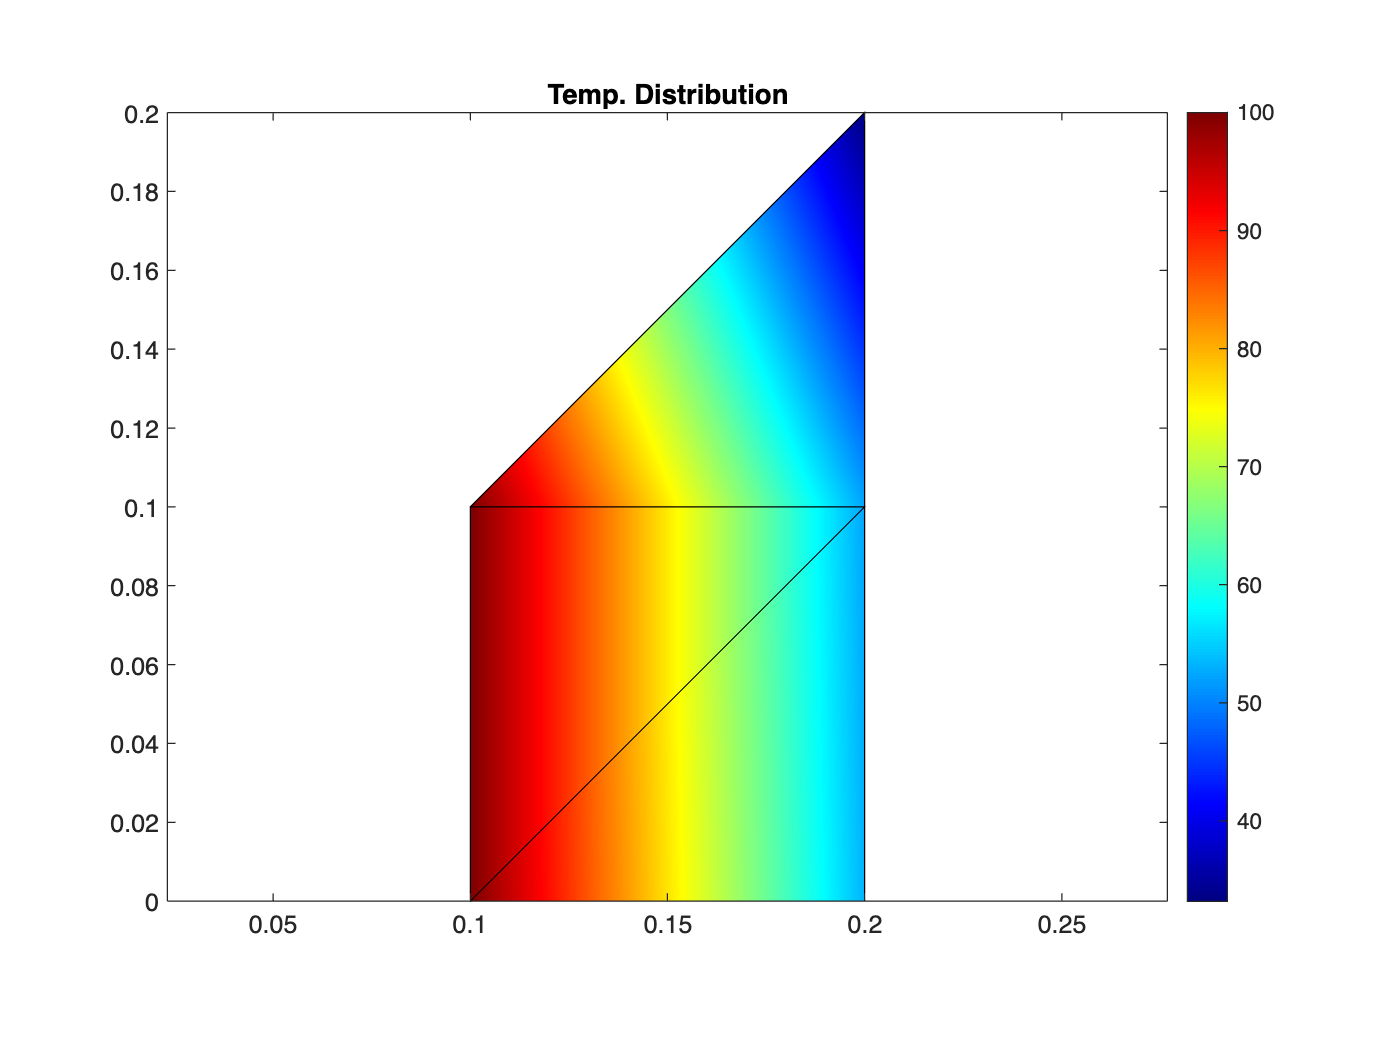


colorScale='jet';
title='Temp. Distribution';
plotContourSolution(nodes,elem,u,title,colorScale)